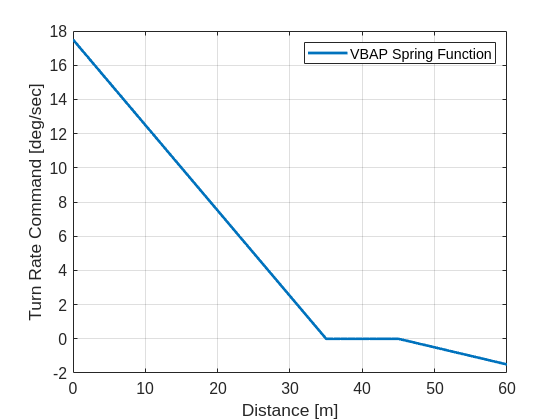

% VBAP spring

dist_boat = 0:1:60;

d0 = 45;
dmin = 35;
dmax = 60;
ko = 0.1;
k2 = 0.5;

head_boat = -10;
turn_boat = zeros(size(dist_boat));

 for ii=1:numel(dist_boat)
        if dist_boat(ii) <= dmax && dist_boat(ii) >= d0
         turn_boat(ii) = ko*(dist_boat(ii)-d0)*sign(head_boat);
         elseif dist_boat(ii) < dmin
         turn_boat(ii) = k2*sign(head_boat)*(dist_boat(ii) - dmin);
        else
        turn_boat(ii) = 0;
        end
   
 end
    figure()
    clf
    ax = gca;
ax.FontSize = 12;
set(gcf,'color','w');
 plot(dist_boat,turn_boat,'LineWidth',2)
 grid on
 hold on
 xlabel('Distance [m]')
 ylabel('Turn Rate Command [deg/sec]')
legend('VBAP Spring Function')


% VBAP spring
close all
clear



x = -75:1:75;
y = -75:1:75;
dist_boat = (x.^2 + y.^2).^0.5;




d0 = 45;
dmin = 35;
dmax = 60;
ko = 0.1;
k2 = 0.5;



turn_boat = zeros(numel(x),numel(y));
head_boat = -10;
for k =1:numel(x)
    for j = 1:numel(y)
        dist_boat = (x(k)^2 + y(j)^2)^0.5;
                if dist_boat <= dmax && dist_boat >= d0
                 turn_boat(k,j) = ko*(dist_boat-d0)*sign(head_boat);
                 elseif dist_boat < dmin
                 turn_boat(k,j) = k2*sign(head_boat)*(dist_boat - dmin);
                else
                turn_boat(k,j) = 0;
                end
           
         
    end
end



%     figure()
%     clf
%  plot(dist_boat,turn_boat,'LineWidth',2)
%  grid on
%  hold on
%  xlabel('Distance [m]')
%  ylabel('Rate Command [deg/s]')
%  xline(16,'r','linewidth',2)
%  legend('VBAP Function','SS spacing')



figure()
clf()
ax = gca;
ax.FontSize = 12;
set(gcf,'color','w');
sl =surfl(x,y,turn_boat)

sl =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [151×151 double]
           YData: [151×151 double]
           ZData: [151×151 double]
           CData: [151×151 double]

  Show all properties


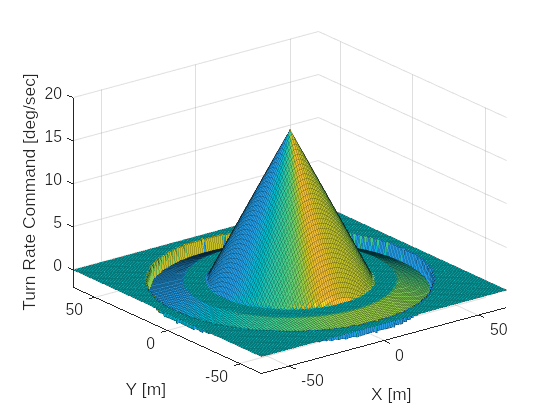

sl =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [151×151 double]
           YData: [151×151 double]
           ZData: [151×151 double]
           CData: [151×151 double]

  Show all properties


grid on
xlabel('X [m]')
ylabel('Y [m]')
zlabel('Turn Rate Command [deg/sec]')
axis([-65 65 -65 65 -2 20])
sl.EdgeAlpha = 0.2